clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);

## Three-step with alpha = 0


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param = control.DesignProcedureSOF(param,1,{[-1,1]},0.01);

Uncertainties = Uncertainties(:,:,1) =

    -1


Uncertainties(:,:,2) =

     1


ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0295
       solvertime: 0.0071
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


 
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|          Constraint|   Primal residual|   Dual residual|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality|           0.32685|      2.6088e-13|
|   #2|   Matrix inequality|           0.58147|      1.9951e-13|
|   #3|   Matrix inequality|           0.16845|      4.4232e-13|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals.|
| In practice, many solvers converge to slightly infeasible    |
| solutions, which may cause some residuals to be negative.    |
| It is up to the user to judge the importance and impact of   |
| slightly negative residuals (i.e. infeasibilities)           |
| https://yalmip.github.io/command/check/                      |
| https://yalmip.github.io/faq/solutionviolated/               |
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
 


Ksf =     2.8478    4.0335    2.8093         0         0         0         0         0         0         0         0         0
         0         0         0    2.6601    3.6688    2.5973         0         0         0         0         0         0
         0         0         0         0         0         0    2.6789    3.4805    2.5418         0         0         0
         0         0         0         0         0         0         0         0         0    2.6748    4.1247    2.7757


sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0321
       solvertime: 0.0292
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


 
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|               Constraint|   Primal residual|   Dual residual|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|        Matrix inequality|        1.4953e-08|      1.1694e-10|
|   #2|        Matrix inequality|        1.5861e-07|      1.2522e-10|
|   #3|        Matrix inequality|        2.8225e-08|      1.3709e-10|
|   #4|        Matrix inequality|        1.6872e-08|      9.2284e-10|
|   #5|   Elementwise inequality|             2.192|      7.7659e-09|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals. |
| In practice, many solvers converge to slightly infeasible         |
| solutions, which may cause some residuals to be negative.         |
| It is up to the user to judge the importance and impact of        |
| slightly negative residuals (i.e. infeasibilities)                |
| https://yalmip.g

sigma_calc = 2.1920

P_min =     7.7939   -8.7866    1.5277         0         0         0         0         0         0         0         0         0
   -8.7866   13.1818   -1.5204         0         0         0         0         0         0         0         0         0
    1.5277   -1.5204    1.5971         0         0         0         0         0         0         0         0         0
         0         0         0    5.9014   -6.4030    1.2295         0         0         0         0         0         0
         0         0         0   -6.4030    9.9022   -1.1881         0         0         0         0         0         0
         0         0         0    1.2295   -1.1881    1.6338         0         0         0         0         0         0
         0         0         0         0         0         0    6.4434   -7.0764    1.3293         0         0         0
         0         0         0         0         0         0   -7.0764   10.8243   -1.2970         0         0         0
         0         0    

Check SSD and eig for vertices i = 1


ans =  -165.5896
   -0.1352
    1.1078
 -146.3030
 -135.2720
 -124.2019
   -0.2000
   -0.1772
   -0.1542
    1.1123


ans =  -157.7399
 -138.8193
 -129.5832
 -118.9198
   -1.0441
   -0.9999
   -0.9586
   -0.9280
   -0.0000
   -0.0000


Check SSD and eig for vertices i = 2


ans =  -197.7244
 -175.8640
 -160.9342
 -143.3037
    0.8836
    0.6500
    0.6173
    0.5651
   -0.1625
   -0.1877


ans =  -151.5451
 -132.1822
 -125.9439
 -114.5055
   -2.0437
   -1.5297
   -0.8795
   -0.7342
   -0.0521
   -0.0313


sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0251
       solvertime: 0.0030
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


ans = 114.5985

sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0267
       solvertime: 0.0069
             info: 'Infeasible problem (<a href="yalmip.github.io/debugginginfeasible">learn to debug</a>) (MOSEK-SDP)'
          problem: 1


 
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|          Constraint|   Primal residual|   Dual residual|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality|           -1.1628|      0.00017086|
|   #2|   Matrix inequality|           -1.1628|      0.00021007|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals.|
| In practice, many solvers converge to slightly infeasible    |
| solutions, which may cause some residuals to be negative.    |
| It is up to the user to judge the importance and impact of   |
| slightly negative residuals (i.e. infeasibilities)           |
| https://yalmip.github.io/command/check/                      |
| https://yalmip.github.io/faq/solutionviolated/               |
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
 


Ksof = 1.0e-34 *

    0.4320    0.1662         0         0         0         0         0         0
         0         0    0.5234    0.1646         0         0         0         0
         0         0         0         0    0.4855    0.1586         0         0
         0         0         0         0         0         0    0.4998    0.1686


Evaluation of design procedure for three-step SOF 
Eigenvalues of the decoupled systems are all negative 


ans =    -0.0311   -4.0059         0   -0.0312   -4.0442         0   -0.0311   -4.0059         0   -0.0311   -4.0058         0


Eigenvalues of the coupled systems are all negative 


ans =    -0.0311   -4.0059    0.0000   -4.0442   -4.0059   -4.0058   -0.0311   -0.0311   -0.0312   -0.0000    0.0000   -0.0000


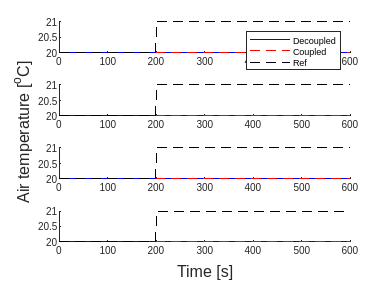

util.SimulateLinearStep(param,"Examination_Output_Feedback_alpha0",0);

util.CalculatePerformanceLPV(param,{[-1,1]});

Gamma = 80.0000

ans = 1.0e+07 *

   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0838
    0.0843


ans = 1.0e+07 *

    3.7702   -0.0120    0.0000         0         0         0         0         0         0         0         0         0   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0120    0.0844    0.0000         0         0         0         0         0         0         0         0         0   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
         0         0         0    3.6228   -0.0153    0.0000         0         0         0         0         0         0   -0.0000   -0.0006    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
         0         0         0   -0.0153    0.0844    0.0000         0         0         0         0         0         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.000

P_out = 1.0e+07 *

    3.7702   -0.0120    0.0000         0         0         0         0         0         0         0         0         0   -0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0120    0.0844    0.0000         0         0         0         0         0         0         0         0         0   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
         0         0         0    3.6228   -0.0153    0.0000         0         0         0         0         0         0   -0.0000   -0.0006    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
         0         0         0   -0.0153    0.0844    0.0000         0         0         0         0         0         0   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0

## Three-step with alpha = 0.5


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param = control.DesignProcedureSOF(param,0,{[-1,1]},-.4);

P_min =    19.6258   -4.7644    2.7912         0         0         0         0         0         0         0         0         0
   -4.7644    7.4580    1.9682         0         0         0         0         0         0         0         0         0
    2.7912    1.9682   18.0991         0         0         0         0         0         0         0         0         0
         0         0         0   17.8601   -4.7603    2.2927         0         0         0         0         0         0
         0         0         0   -4.7603    7.1160    1.7400         0         0         0         0         0         0
         0         0         0    2.2927    1.7400   16.7743         0         0         0         0         0         0
         0         0         0         0         0         0   17.2162   -4.7019    2.1896         0         0         0
         0         0         0         0         0         0   -4.7019    7.0987    1.7021         0         0         0
         0         0    

Evaluation of design procedure for three-step SOF 
Eigenvalues of the decoupled systems are all negative 


ans =   -4.0025 + 0.0000i  -0.0173 + 0.0586i  -0.0173 - 0.0586i  -4.0320 + 0.0000i  -0.0217 + 0.1141i  -0.0217 - 0.1141i  -3.9921 + 0.0000i  -0.0225 + 0.1218i  -0.0225 - 0.1218i  -3.9907 + 0.0000i  -0.0231 + 0.1262i  -0.0231 - 0.1262i


Eigenvalues of the coupled systems are all negative 


ans =   -4.0173 + 0.0000i  -3.9985 + 0.0000i  -3.9773 + 0.0000i  -3.9710 + 0.0000i  -0.0192 + 0.0868i  -0.0192 - 0.0868i  -0.0281 + 0.1641i  -0.0281 - 0.1641i  -0.0330 + 0.1932i  -0.0330 - 0.1932i  -0.0308 + 0.1809i  -0.0308 - 0.1809i


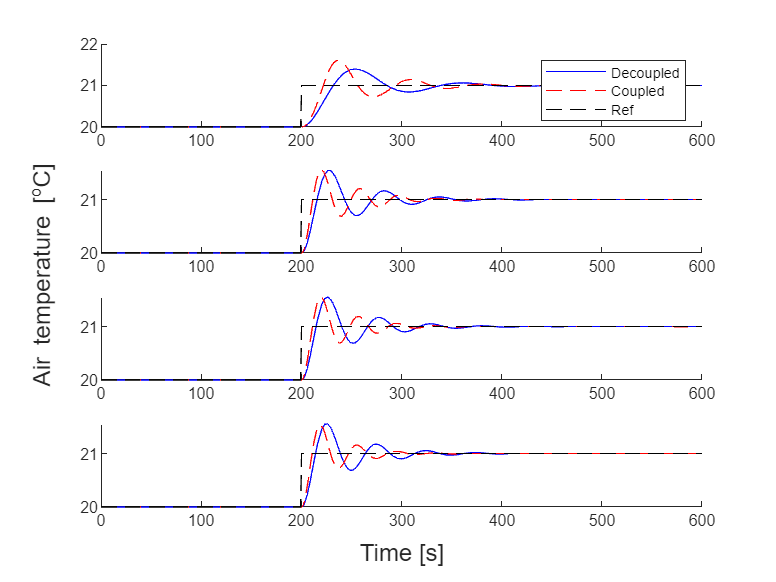

util.SimulateLinearStep(param,"Examination_Output_Feedback_alpha",0);

## ILMI algorithm


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param = control.DesignProcedureSOF_ILMI(param,0,{[-1,1]});

alpha_min = 0.1675

alpha_min = -0.0874

Evaluation of design procedure for ILMI SOF 
Solved the problem in 2 iterations
The solution had alpha: -0.087372 
Eigenvalues of the decoupled systems are all negative 


ans =    -3.5386   -0.4112   -0.0872   -3.5731   -0.3998   -0.1025   -3.5264   -0.3993   -0.1112   -3.5092   -0.4261   -0.1015


Eigenvalues of the coupled systems are all negative 


ans =   -3.0458 + 0.0000i  -2.5568 + 0.0000i  -2.3891 + 0.0000i  -0.9089 + 0.0000i  -1.9714 + 0.2443i  -1.9714 - 0.2443i  -1.3958 + 0.0000i  -1.5860 + 0.0000i  -0.0800 + 0.0000i  -0.0980 + 0.0000i  -0.0920 + 0.0000i  -0.0910 + 0.0000i


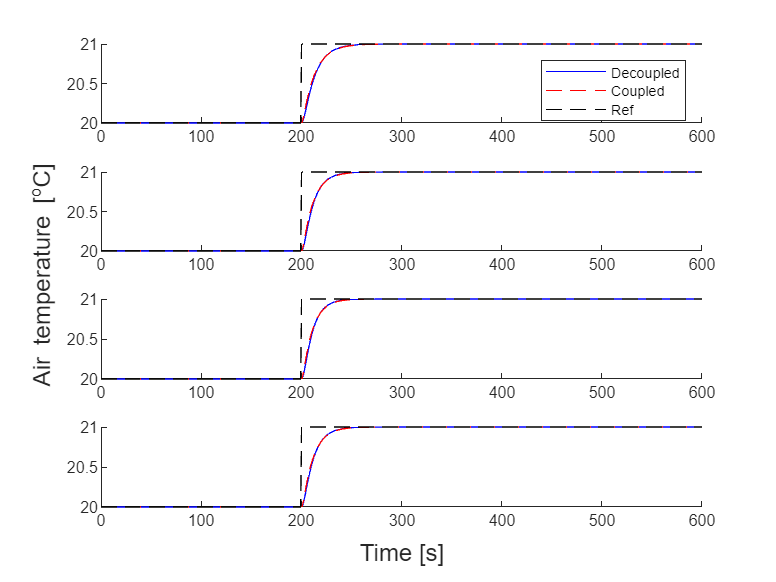

util.SimulateLinearStep(param,"Examination_Output_Feedback_ILMI",0);